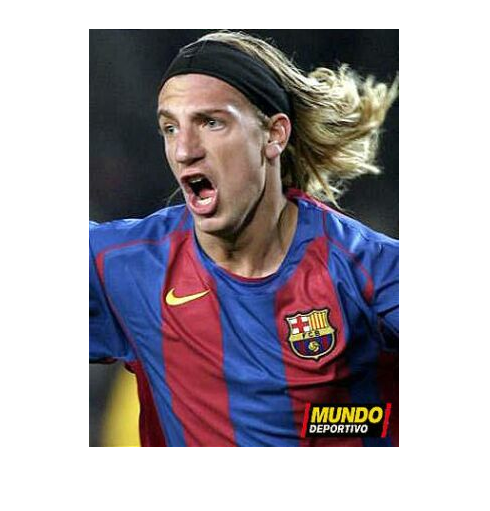

clear all
image=imread('05.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

numBlocks = 4 

numBlocks = 4

rowSize = uint32(row/numBlocks)

rowSize = uint32
105

colSize = uint32(col/numBlocks)

colSize = uint32
78

pixelsBlock = rowSize * colSize

pixelsBlock = uint32
8190


endrow = uint32(row*8)

endrow = uint32
3344

endcol = uint32(col*5)

endcol = uint32
1550

redPixels = 102

bluePixels = 235

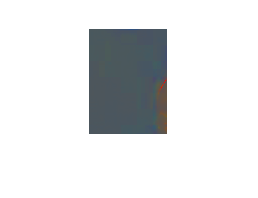

redPixels = 302

bluePixels = 152

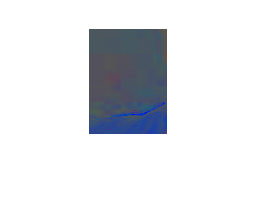

redPixels = 895

bluePixels = 928

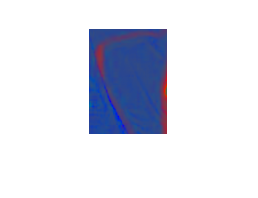

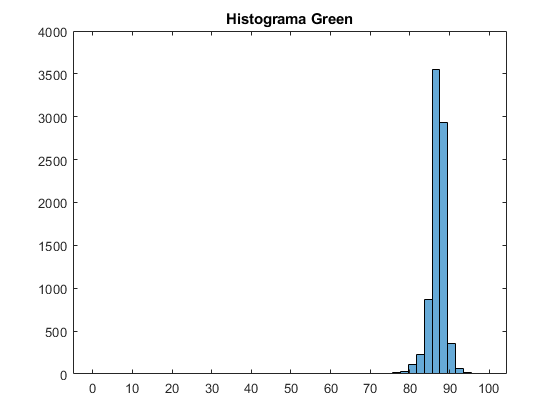

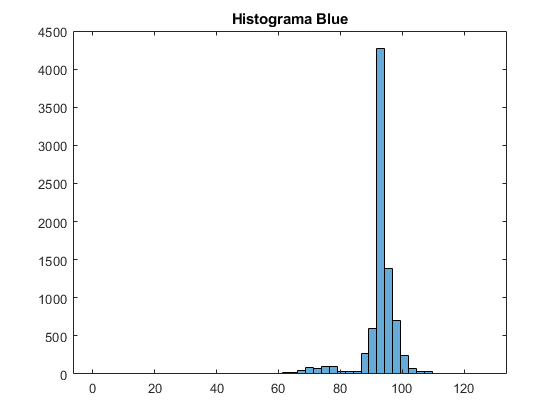

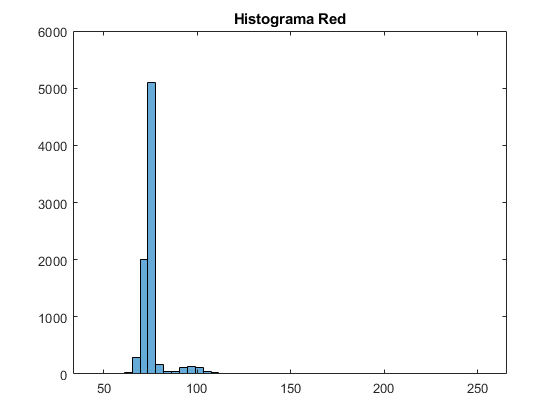

redPixels = 1310

bluePixels = 2570

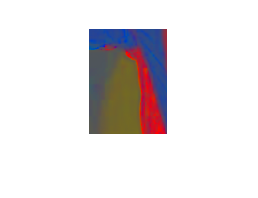

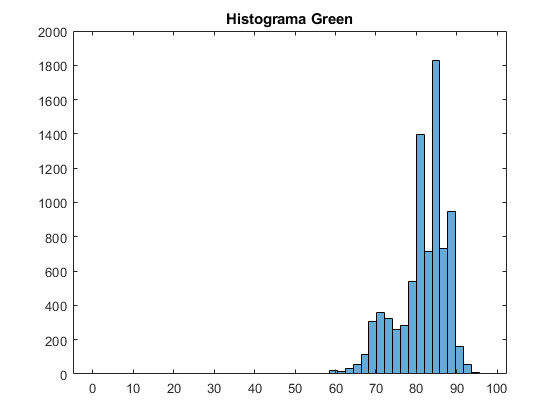

redPixels = 630

bluePixels = 841

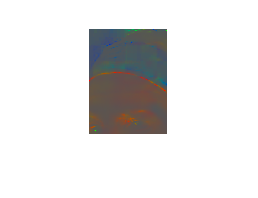

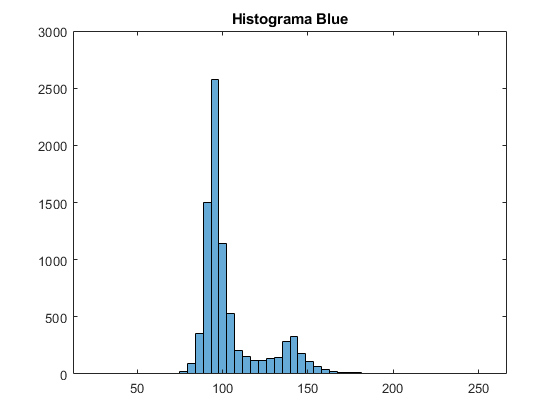

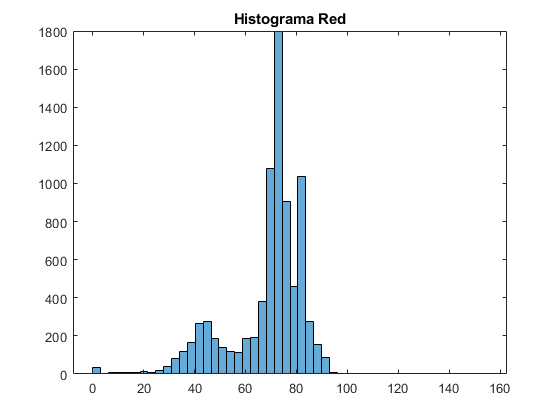

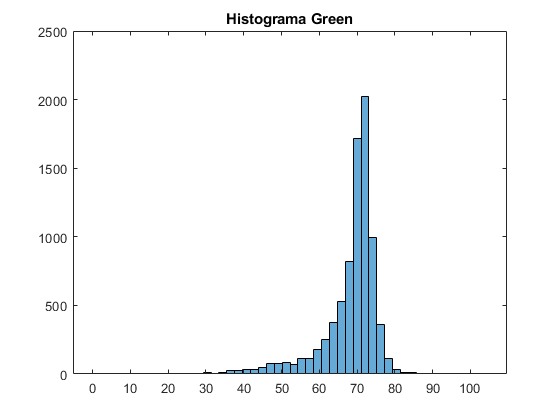

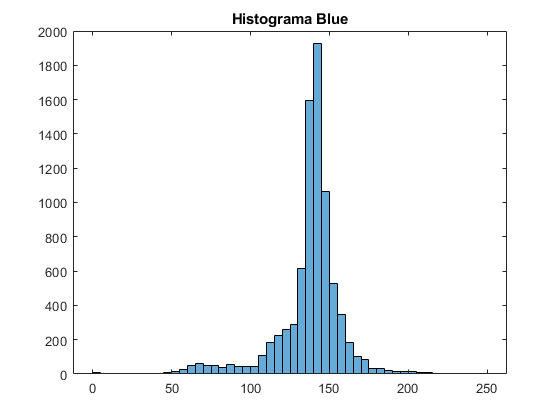

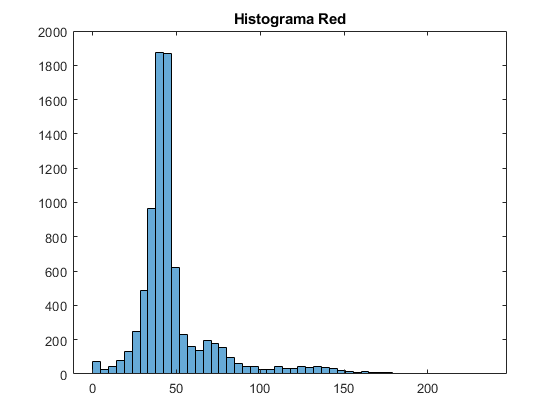

redPixels = 965

bluePixels = 820

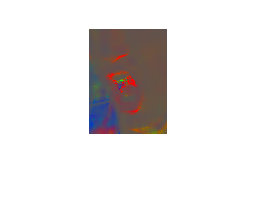

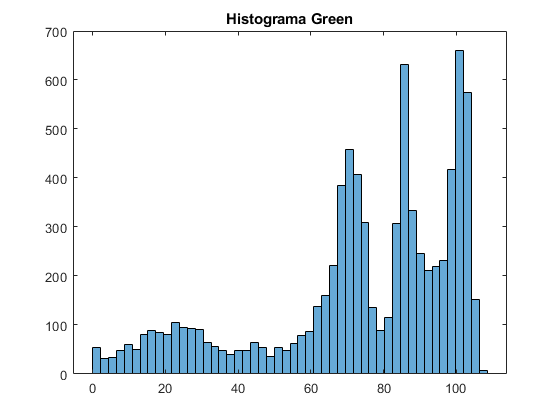

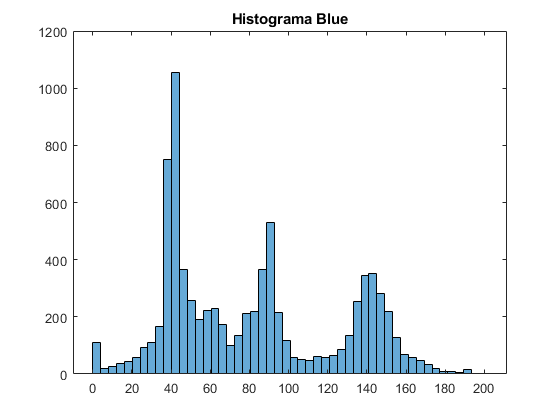

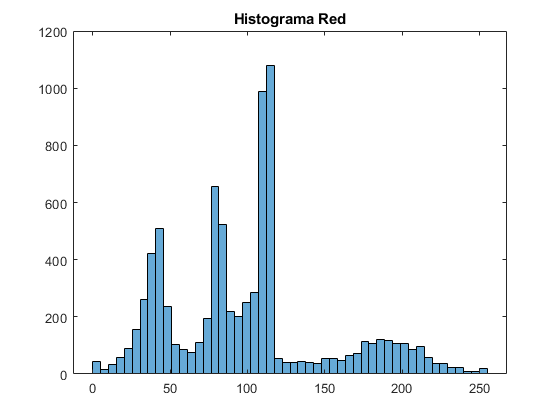

redPixels = 1003

bluePixels = 2521

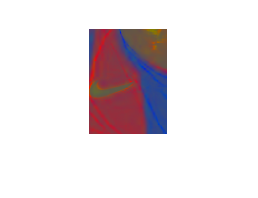

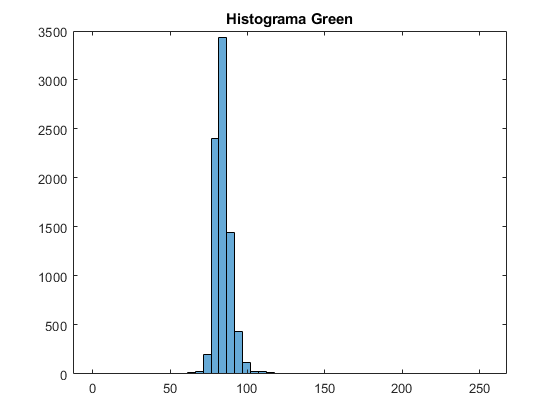

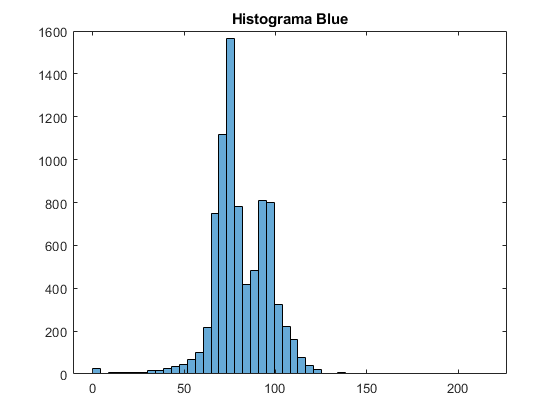

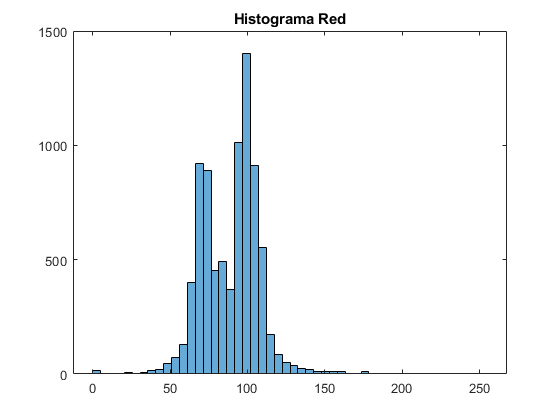

redPixels = 655

bluePixels = 3537

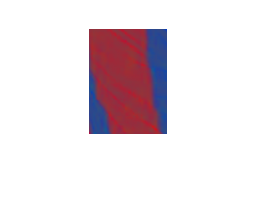

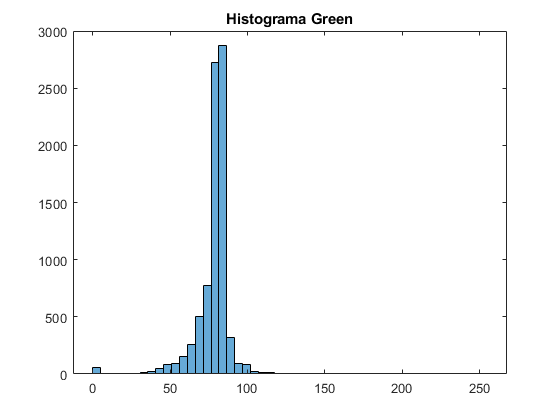

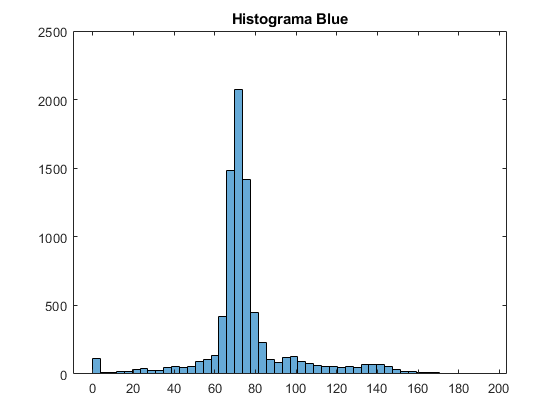

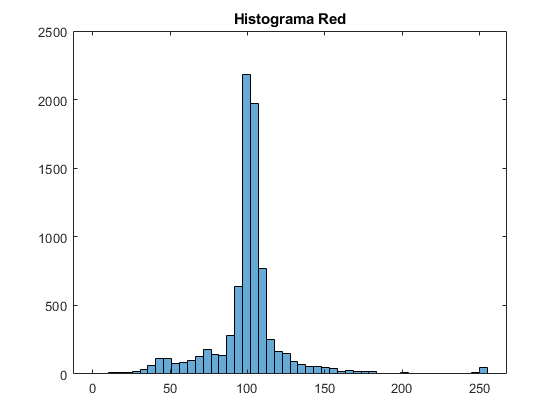

redPixels = 1090

bluePixels = 1123

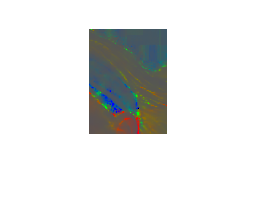

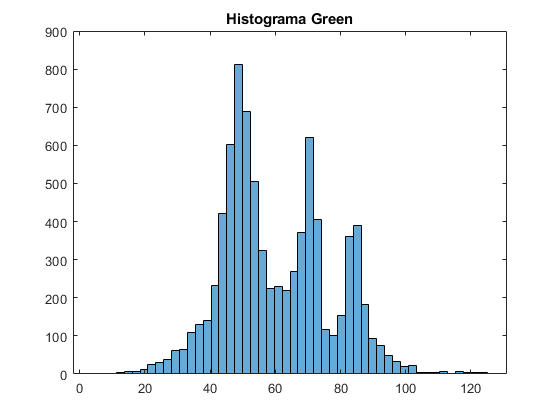

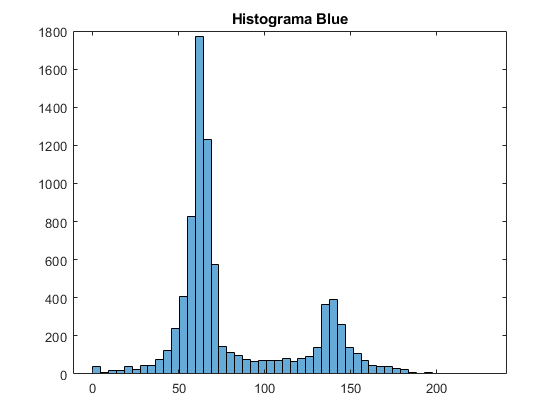

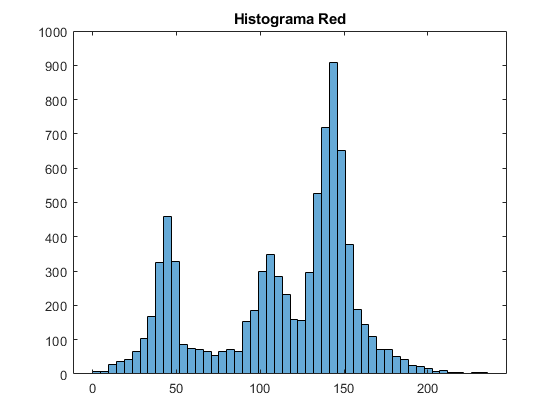

redPixels = 2293

bluePixels = 1679

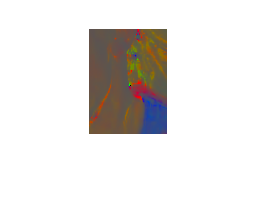

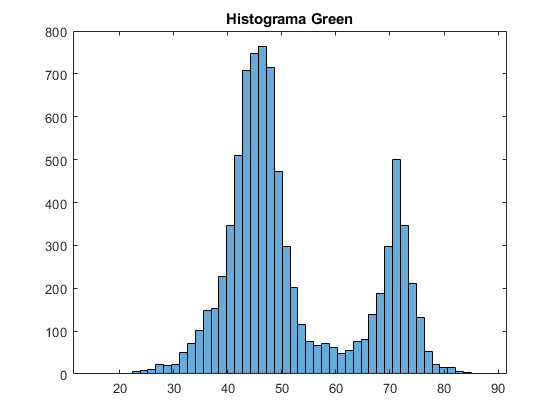

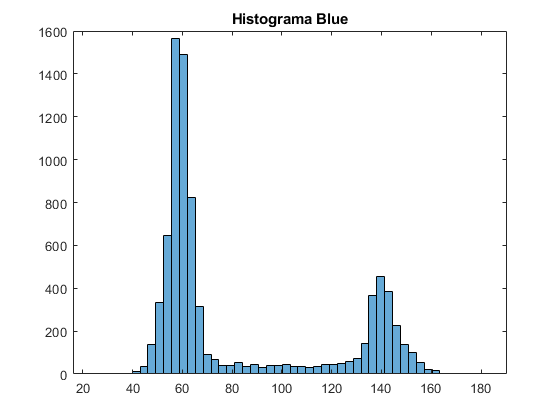

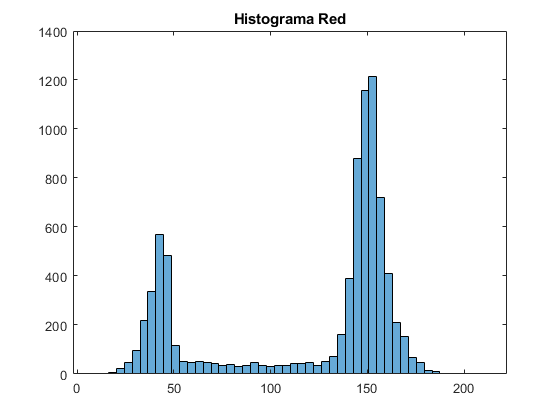

redPixels = 1662

bluePixels = 2057

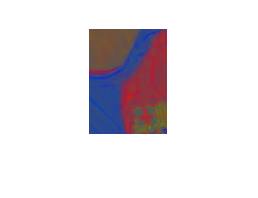

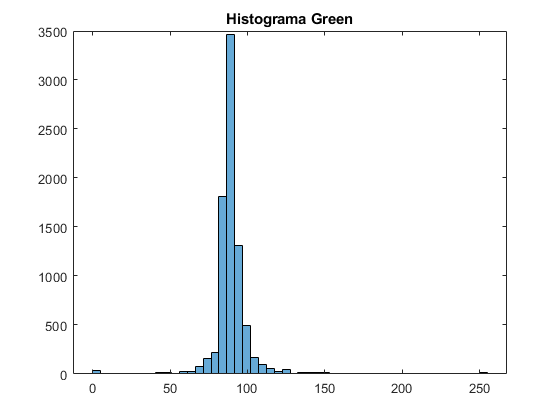

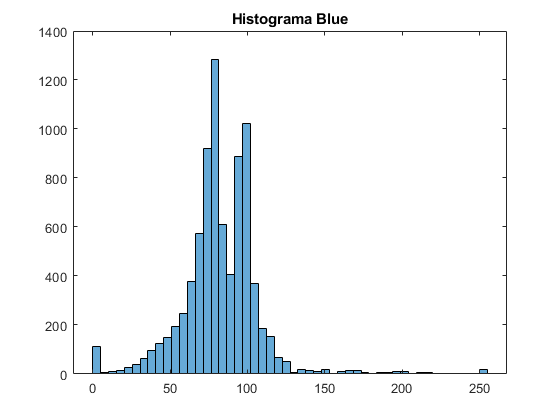

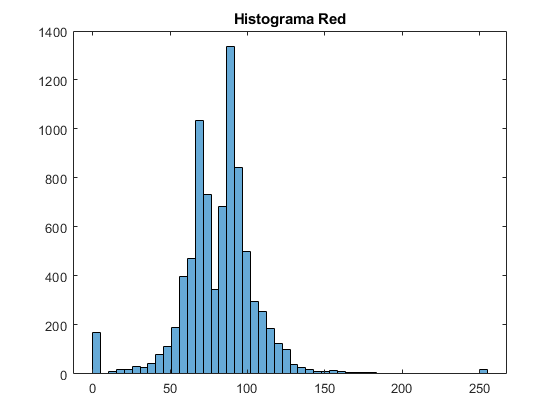

redPixels = 1139

bluePixels = 1153

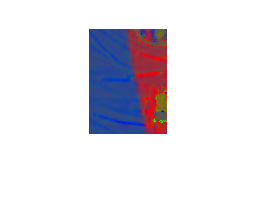

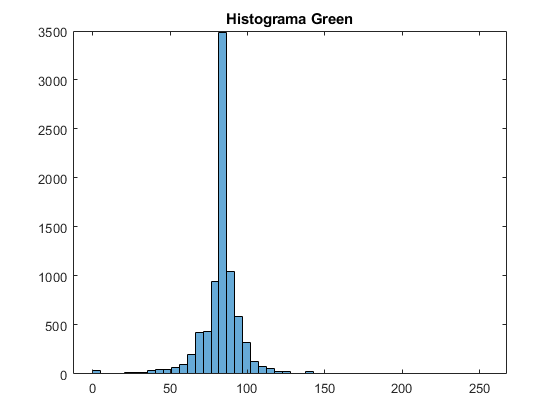

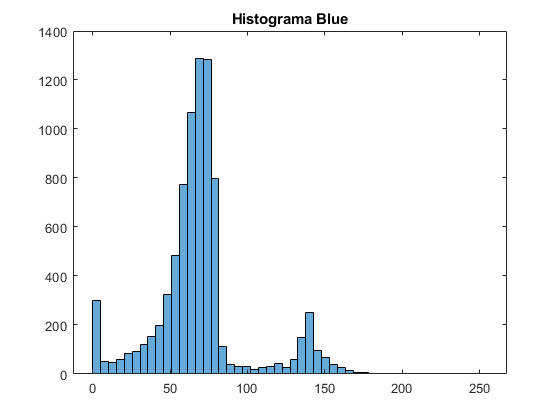

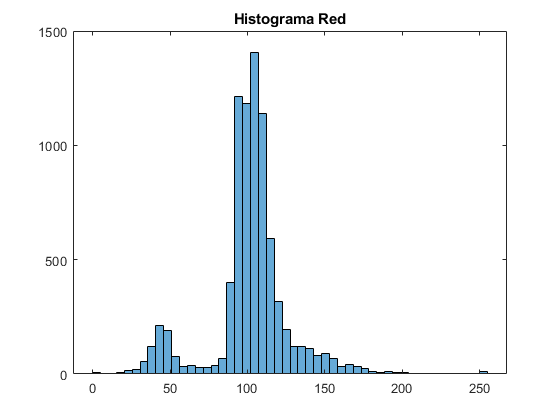

redPixels = 802

bluePixels = 648

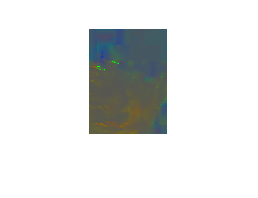

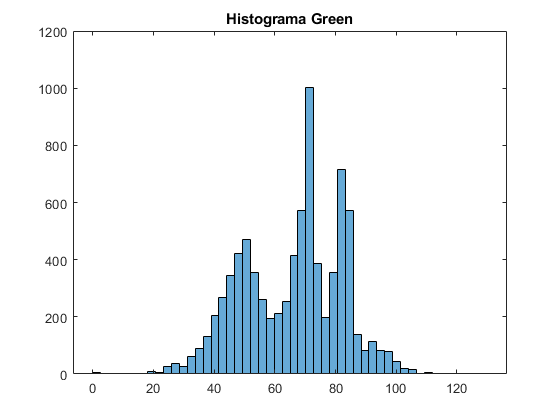

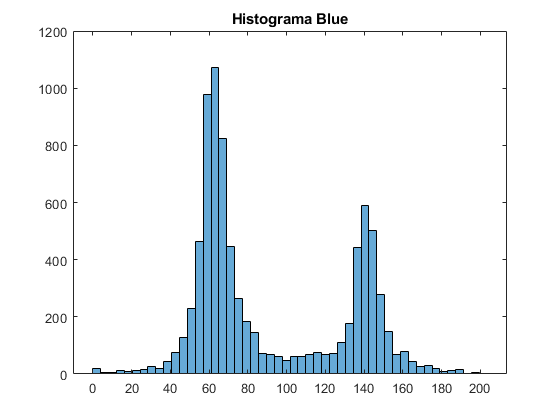

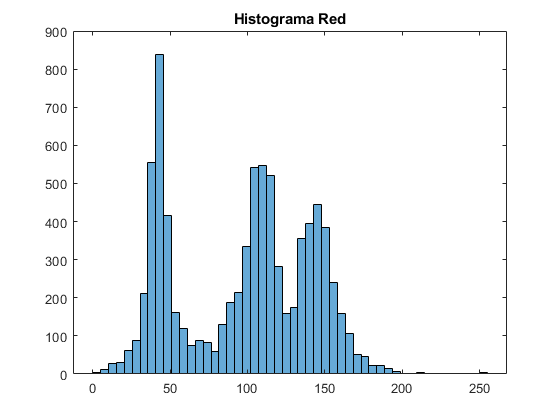

redPixels = 1324

bluePixels = 894

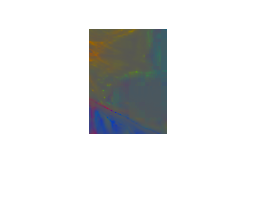

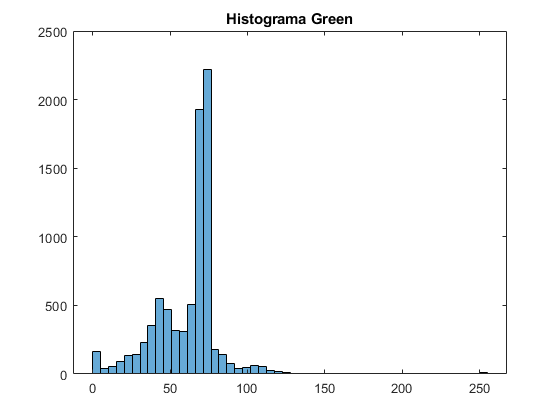

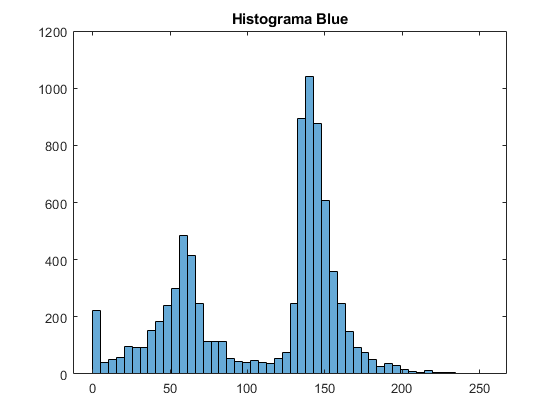

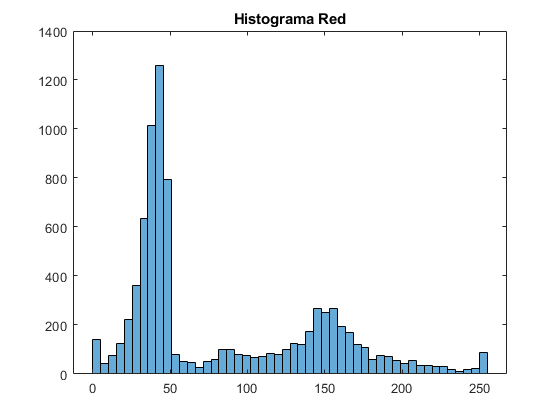

redPixels = 1009

bluePixels = 1528

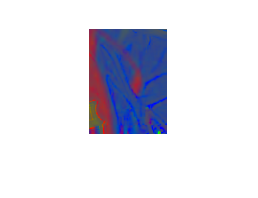

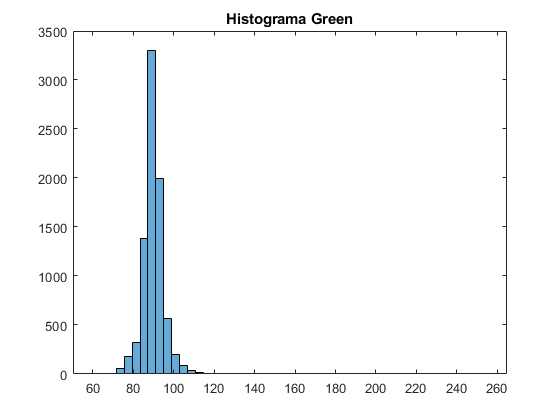

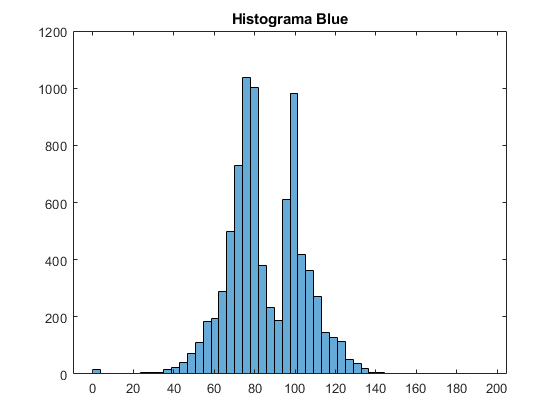

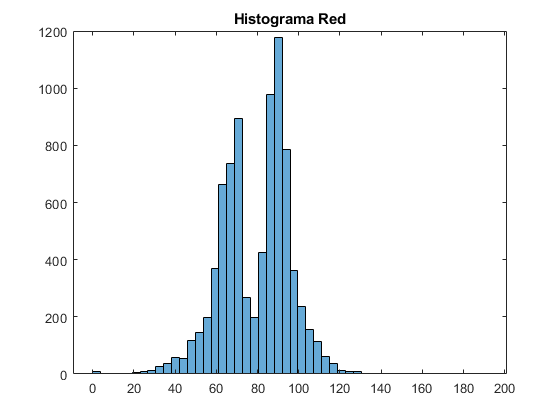

redPixels = 608

bluePixels = 472

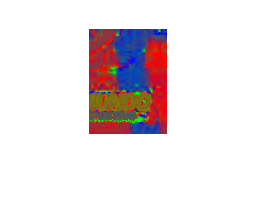

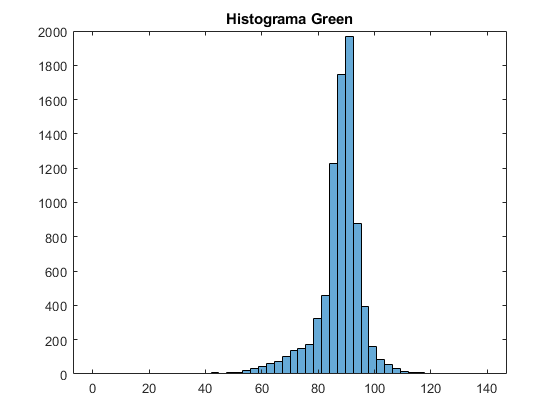

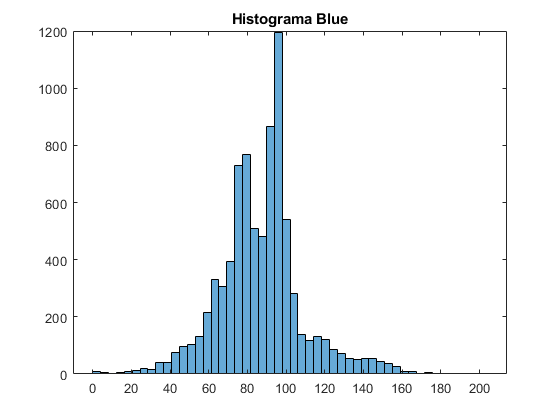

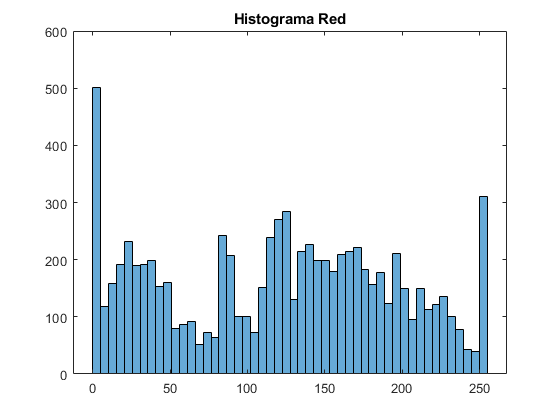

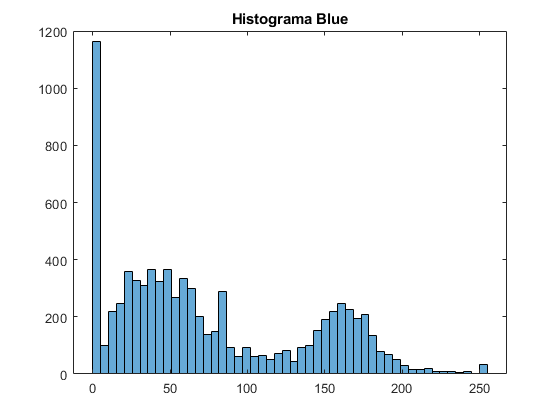

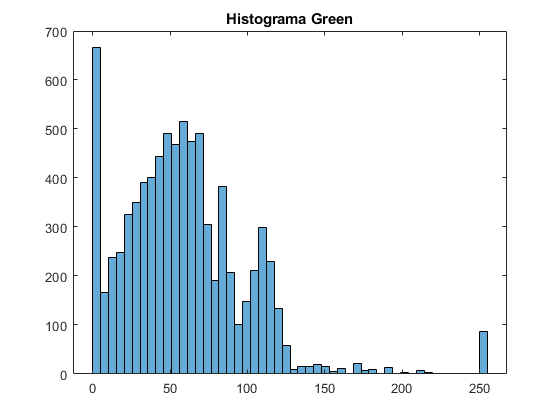


redPixels = 0;
bluePixels = 0;
greenPixels = 0;
isBarsa = 0;

for i = 1:numBlocks
    for j = 1:numBlocks
        startrow = j*rowSize - rowSize -1;
        startcol = i*colSize - colSize -1;
        if (i == 1)
            startcol = i*colSize - colSize + 1;
        end
        if (j == 1)
            startrow = j*rowSize - rowSize + 1;

        end
        endrow = startrow + rowSize -1;
        endcol = startcol + colSize -1;
        redPixels = 0;
        bluePixels = 0;
        greenPixels = 0;
        for y = startrow:endrow 
            for x = startcol:endcol 
              Red = Image_red(y,x);
              Green = Image_green(y,x);
              Blue = Image_blue(y,x);
              
              if (Red >= 75 && Red <= 125)
                  redPixels = redPixels + 1;
              end
              
              if (Blue >= 60 && Blue <= 90)
                  bluePixels = bluePixels + 1;
              end
            
              NormalizedRed = Red/(Red + Green + Blue);
              NormalizedGreen = Green/(Red + Green + Blue);
              NormalizedBlue = Blue/(Red + Green + Blue);
            
              Image_red(y,x) = NormalizedRed;
              Image_green(y,x) = NormalizedGreen;
              Image_blue(y,x) = NormalizedBlue;
            end
        end
        redPixels
        bluePixels
        if (redPixels >= 0.5*pixelsBlock)
            if (bluePixels >= 0.5*pixelsBlock)
                isBarsa = 1
            end
        end
%         Descomentar per veure com genera els blocks
        image(:,:,1) = Image_red;
        image(:,:,2) = Image_green;
        image(:,:,3) = Image_blue;
        figure; imshow(uint8(255*image(startrow:endrow,startcol:endcol,:)));
        figure; histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')
        figure; histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')
        figure; histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')
    end
end


image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

redPixels

redPixels = 608

bluePixels

bluePixels = 472

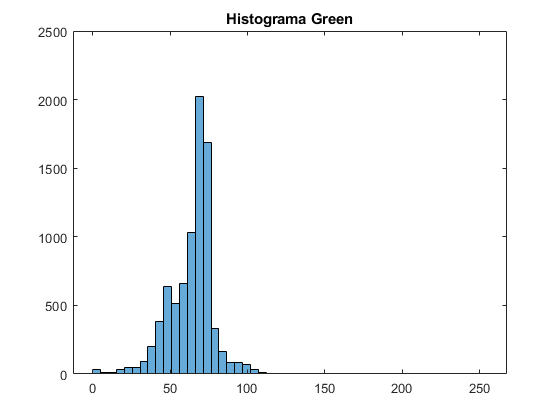

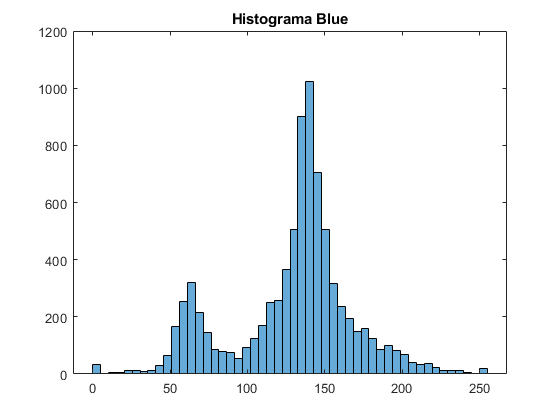

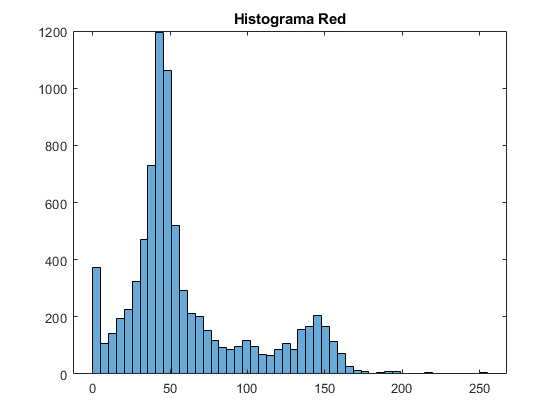

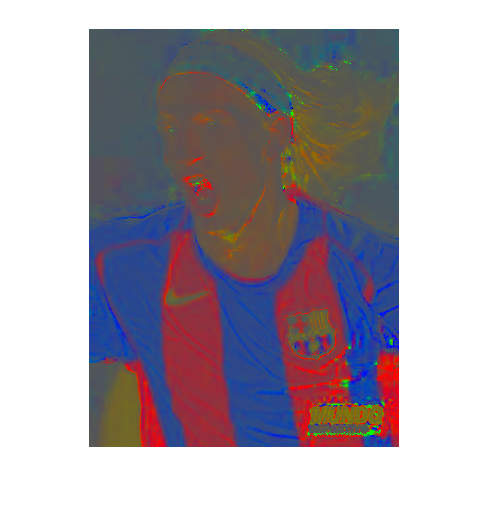


figure; imshow(uint8(255*image));

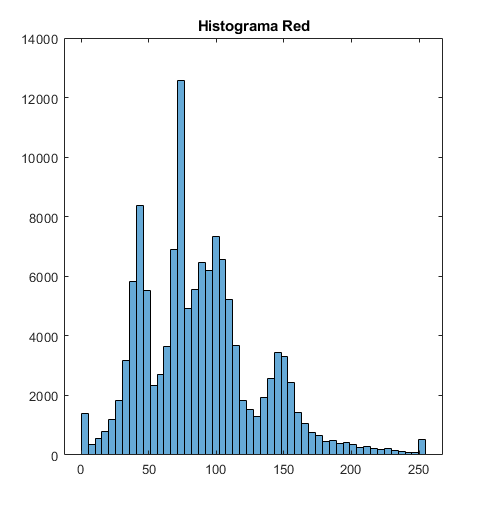


% histogram(image, nBins)
histogram(Image_red(:,:)*255, 50), title('Histograma Red')

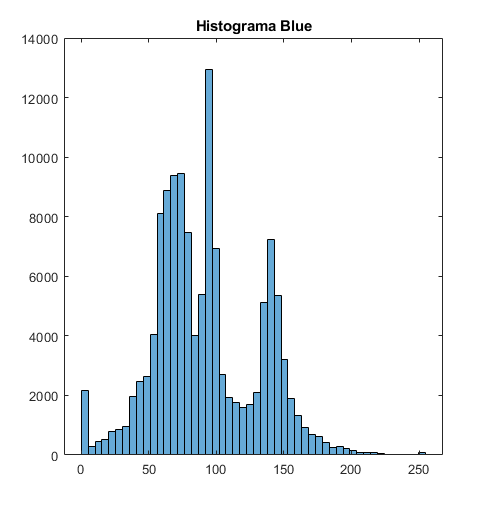

histogram(Image_blue(:,:)*255,50), title('Histograma Blue')

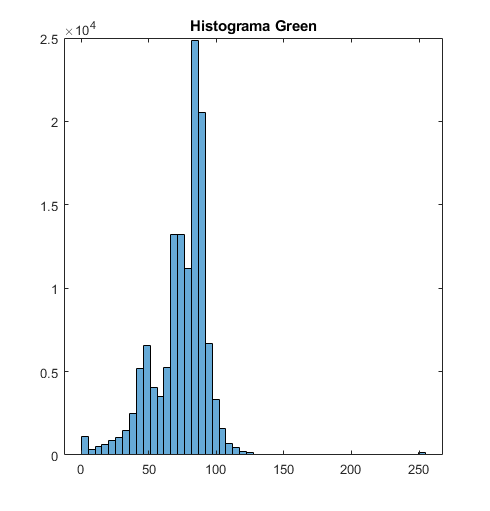

histogram(Image_green(:,:)*255,50), title('Histograma Green')